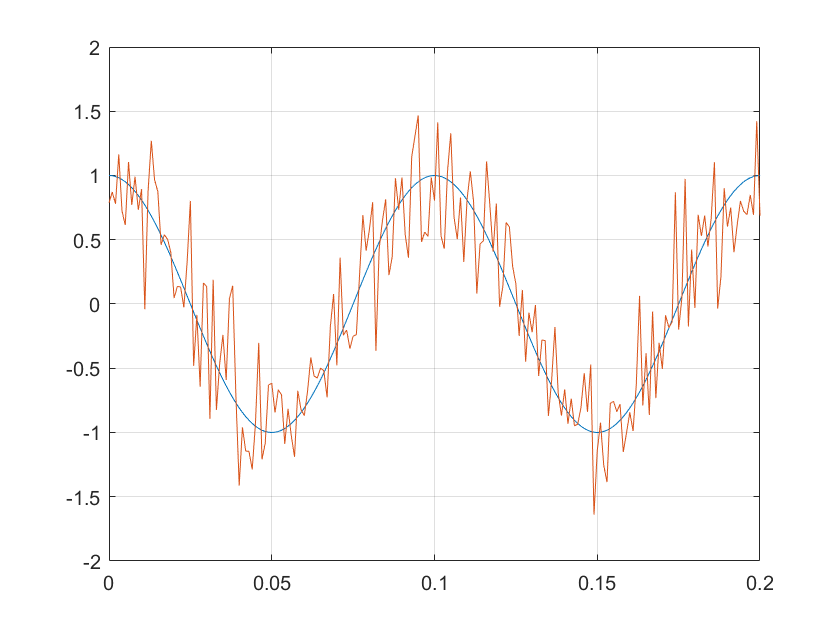

t = 0:1/1000:1;
sine_wave = cos(2*pi*10*t);
plot(t,sine_wave)
%in = zeros(1,100);
%out = awgn(in,10);
%stem(out,'LineWidth',1,'Marker','.'); grid on;
xlim([0 0.2]);
ylim([-2 2]);
grid on;
hold on;
sine_noise = awgn(sine_wave,10);
plot(t,sine_noise);
hold off;

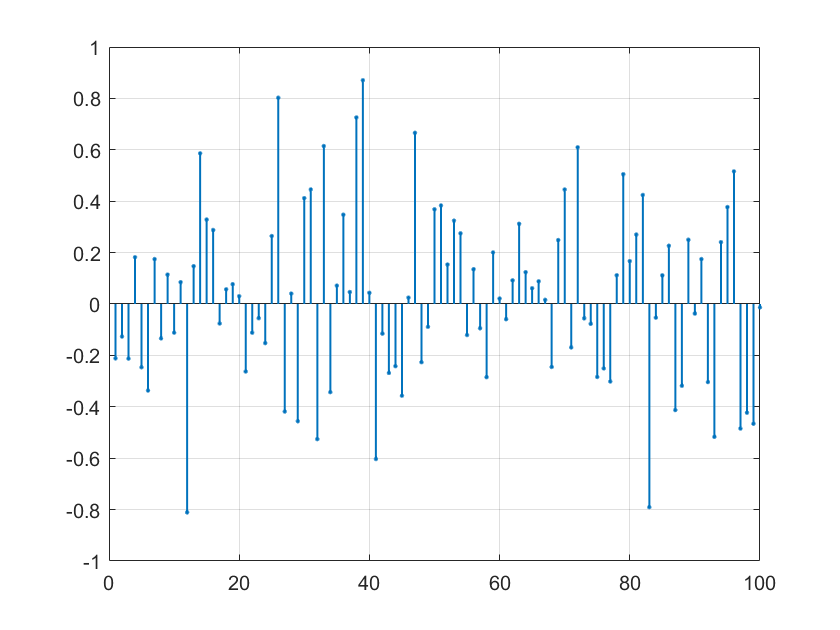


noise = sine_noise - sine_wave;
stem(noise,'LineWidth',1,'Marker','.'); grid on; xlim([0 100]);

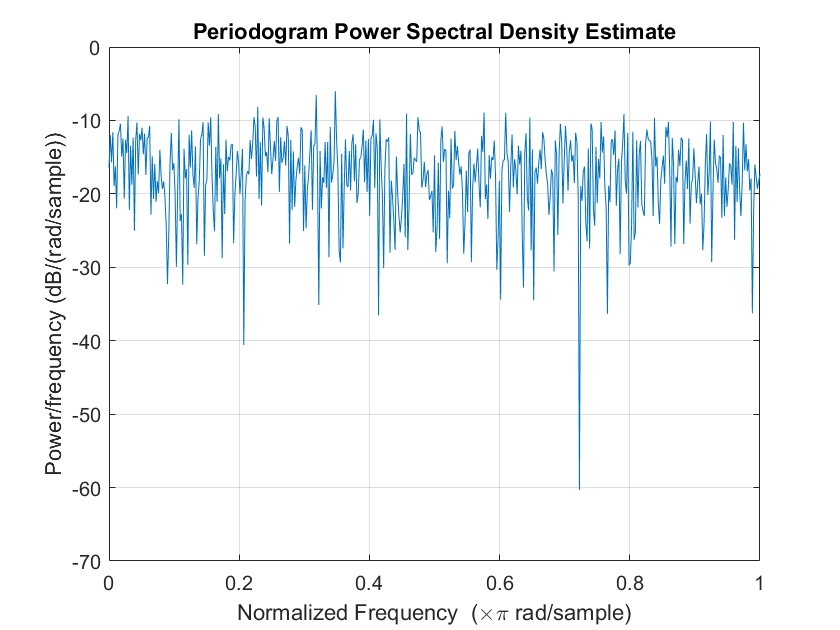

periodogram(noise)

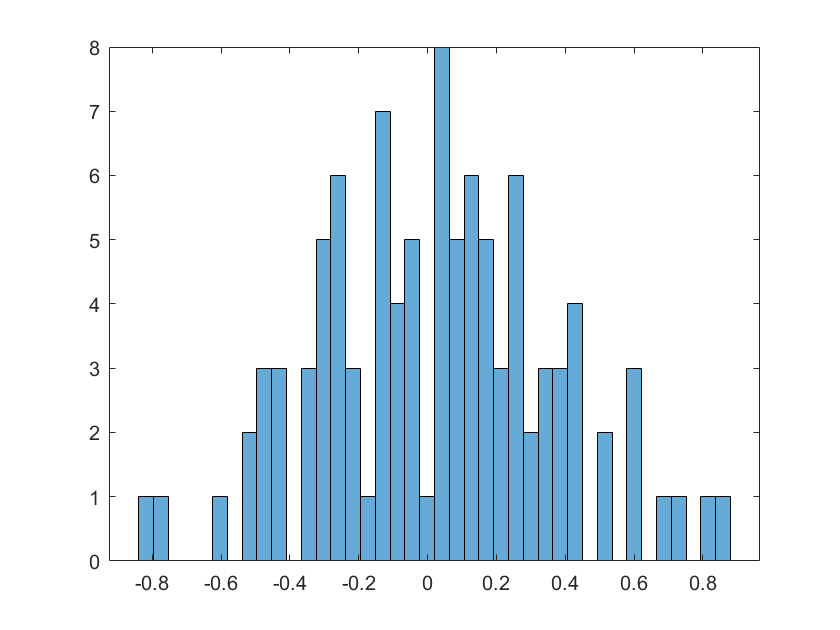

histogram(noise,100)

sine_noise2 = custom_awgn(sine_wave,10);
noise2 = sine_noise2 - sine_wave;
stem(noise2,'LineWidth',1,'Marker','.'); grid on; xlim([0 100]);